# Modelo robot movil

## Constantes

syms a b theta xp yp tp r t 

%medidas
a = 11.78/2;
b = 9.13/2;
r = 1.19;
%Tiempo en el que se llegara al lugar [s]
T = 10;
%Posiciones en cm
xi = 0;%x inicial
yi = 0;%y inicial
xf = 100;%x final
yf = 100;%y final
d = sqrt((xf-xi)^2+(yf-yi)^2);
v = d/T;%cm/s
psi = atan2(yf-yi,xf-xi);
%Angulos en rad
ti = 0;%theta inicial
tf = pi;%theta final

%velocidades del robot
xp = v*sin(psi)

xp = 10

yp = v*cos(psi)

yp = 10.0000

tp = (pi/4)/T;%rad/s


theta = tp*t %El angulo dependera del tiempo

$$theta = \frac{\pi \,t}{40}$$


RZ = [cos(theta),-sin(theta),0;sin(theta),cos(theta),0;0,0,1]

$$RZ = \left(\begin{array}{ccc} \cos\left(\frac{\pi \,t}{40}\right) & -\sin\left(\frac{\pi \,t}{40}\right) & 0\\ \sin\left(\frac{\pi \,t}{40}\right) & \cos\left(\frac{\pi \,t}{40}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

EI = [xp;yp;tp]

EI =    10.0000
   10.0000
    0.0785


ER = RZ^(-1)*EI

$$ER = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}+\sigma_{2}\\ \sigma_{1}-\sigma_{2}\\ \frac{\pi }{40} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{10\,\cos\left(\frac{\pi \,t}{40}\right)}{{\cos\left(\frac{\pi \,t}{40}\right)}^{2}+{\sin\left(\frac{\pi \,t}{40}\right)}^{2}}\\ \sigma_{2}=\frac{10\,\sin\left(\frac{\pi \,t}{40}\right)}{{\cos\left(\frac{\pi \,t}{40}\right)}^{2}+{\sin\left(\frac{\pi \,t}{40}\right)}^{2}} \end{array}$$


%set L
L = sqrt(a*a+b*b)

L = 7.4519

%Set alphas
alpha1 = atan(b/a)

alpha1 = 0.6593

alpha2 = pi-alpha1

alpha2 = 2.4823

alpha3 = pi+alpha1

alpha3 = 3.8009

alpha4 = 2*pi-alpha1

alpha4 = 5.6238

alpha = [alpha1;alpha2;alpha3;alpha4]

alpha =     0.6593
    2.4823
    3.8009
    5.6238


%Set betas
%90 - alpha + angulodeU1
beta1 = pi/2-alpha1

beta1 = 0.9115

beta2 = pi/2-alpha2 

beta2 = -0.9115

beta3 = pi/2-alpha3

beta3 = -2.2301

beta4 = pi/2-alpha4

beta4 = -4.0531

beta = [beta1;beta2;beta3;beta4]

beta =     0.9115
   -0.9115
   -2.2301
   -4.0531


J = [sin(alpha+beta),-cos(alpha+beta),-L*cos(beta)];
J(abs(J)<1e-3)=0

J =     1.0000         0   -4.5650
    1.0000         0   -4.5650
    1.0000         0    4.5650
    1.0000         0    4.5650


C=[cos(alpha+beta), sin(alpha+beta), L*sin(beta)]

C =     0.0000    1.0000    5.8900
    0.0000    1.0000   -5.8900
    0.0000    1.0000   -5.8900
    0.0000    1.0000    5.8900


J2 = r*eye(4)

J2 =     1.1900         0         0         0
         0    1.1900         0         0
         0         0    1.1900         0
         0         0         0    1.1900


C(1,:)*ER==0

$$ans = \frac{589\,\pi }{4000}+\frac{405648192073033433317733025827875\,\cos\left(\frac{\pi \,t}{40}\right)}{40564819207303340847894502572032\,\left({\cos\left(\frac{\pi \,t}{40}\right)}^{2}+{\sin\left(\frac{\pi \,t}{40}\right)}^{2}\right)}-\frac{405648192073033383640157025612765\,\sin\left(\frac{\pi \,t}{40}\right)}{40564819207303340847894502572032\,\left({\cos\left(\frac{\pi \,t}{40}\right)}^{2}+{\sin\left(\frac{\pi \,t}{40}\right)}^{2}\right)}=0$$

A = [J(1,:);J(3,:);C(1,:)]

A =     1.0000         0   -4.5650
    1.0000         0    4.5650
    0.0000    1.0000    5.8900



phip = J*ER/r;
phip = vpa(simplify(phip),3)

$$phip = \left(\begin{array}{c} 11.9\,\sin\left(0.0785\,t+0.785\right)-0.301\\ 11.9\,\sin\left(0.0785\,t+0.785\right)-0.301\\ 11.9\,\sin\left(0.0785\,t+0.785\right)+0.301\\ 11.9\,\sin\left(0.0785\,t+0.785\right)+0.301 \end{array}\right)$$

syms t
VR = vpa(sum(phip*r)/4,3);

X = vpa(VR*t*cos(theta),3);
Y = vpa(VR*t*sin(theta),3);
t = 0:0.1:T

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


X = eval(X)

X =          0    1.0044    2.0241    3.0587    4.1078    5.1710    6.2479    7.3382    8.4414    9.5570   10.6847   11.8240   12.9745   14.1357   15.3072   16.4885   17.6791   18.8787   20.0866   21.3025   22.5259   23.7562   24.9929   26.2357   27.4839   28.7371   29.9948   31.2565   32.5216   33.7896   35.0600   36.3324   37.6061   38.8807   40.1555   41.4302   42.7042   43.9769   45.2478   46.5164   47.7821   49.0445   50.3029   51.5569   52.8059   54.0493   55.2868   56.5177   57.7414   58.9576


Y = eval(Y)

Y =          0    0.0079    0.0318    0.0720    0.1290    0.2031    0.2945    0.4036    0.5308    0.6763    0.8405    1.0235    1.2258    1.4476    1.6891    1.9505    2.2323    2.5344    2.8573    3.2010    3.5659    3.9521    4.3597    4.7890    5.2401    5.7132    6.2084    6.7258    7.2656    7.8279    8.4127    9.0202    9.6505   10.3036   10.9795   11.6783   12.4001   13.1448   13.9125   14.7033   15.5169   16.3536   17.2131   18.0956   19.0008   19.9289   20.8796   21.8529   22.8487   23.8669


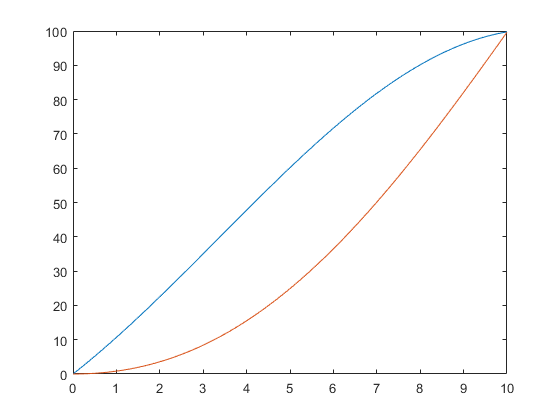

plot(t,X)
hold on
plot(t,Y)
hold off

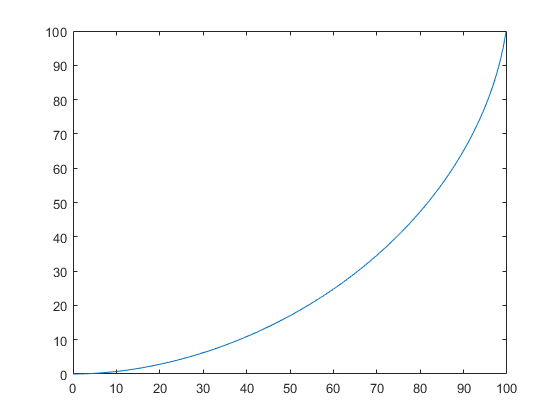

plot(X,Y)

% EI2 = EI*t;
% 
% 
% plot(t,EI2())
% hold on
% % plot(eval(phip(3)*r*t))
% hold off

syms t
R = (r/2)*eye(3)

R =     0.5950         0         0
         0    0.5950         0
         0         0    0.5950


A = R*[cos(theta) cos(theta);sin(theta) sin(theta);1/b -1/b]

$$A = \left(\begin{array}{cc} \frac{119\,\cos\left(\frac{\pi \,t}{40}\right)}{200} & \frac{119\,\cos\left(\frac{\pi \,t}{40}\right)}{200}\\ \frac{119\,\sin\left(\frac{\pi \,t}{40}\right)}{200} & \frac{119\,\sin\left(\frac{\pi \,t}{40}\right)}{200}\\ \frac{119}{913} & -\frac{119}{913} \end{array}\right)$$

phip = pinv(A)*EI;
phi = vpa(phip*t,3);
t = 0:0.1:T

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


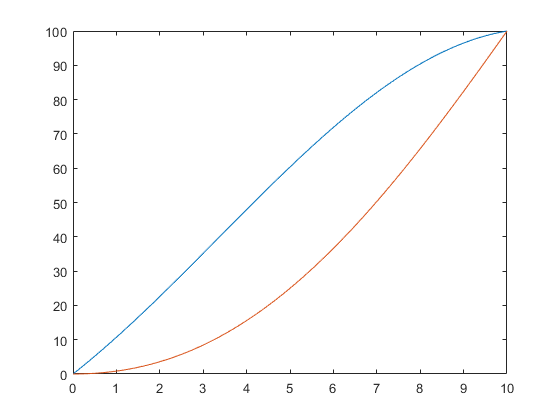

pos = A*phi;
pos = subs(pos,sym('t'),t);
plot(t,pos(1,:))
hold on
plot(t,pos(2,:))
hold off

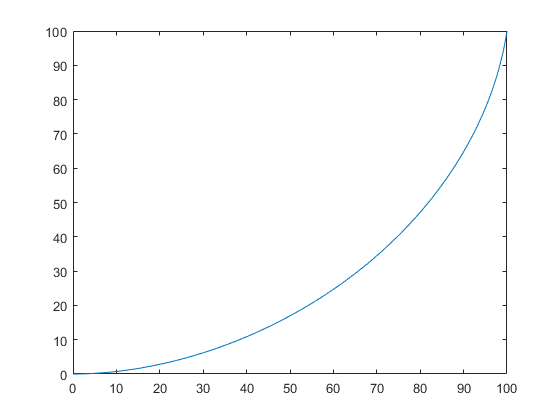

plot(pos(1,:),pos(2,:))